# **Materials classification - A1**

# Convolutional neural networks

clc; clear all; close all;

## Import dataset

rng(100)

% Training and test images
train_image_data_folder = "Data\image\";

imds = imageDatastore(train_image_data_folder,'IncludeSubFolders',true,'FileExtensions','.jpg','LabelSource','foldernames');
[trainImds,testImds] = splitEachLabel(imds,0.8);

### Create image set

% The training set consists of 900 images and
% the test set consists of 100 images
countEachLabel(trainImds)

ans = 10×2 table
     Label     Count
    _______    _____

    fabric       80 
    foliage      80 
    glass        80 
    leather      80 
    metal        80 
    paper       112 
    plastic      72 
    stone        72 
    water        72 
    wood         72 


countEachLabel(testImds)

ans = 10×2 table
     Label     Count
    _______    _____

    fabric      20  
    foliage     20  
    glass       20  
    leather     20  
    metal       20  
    paper       28  
    plastic     18  
    stone       18  
    water       18  
    wood        18  


### Convolutional Deep Network

net = inceptionv3();
inputSize = net.Layers(1).InputSize

inputSize =    299   299     3


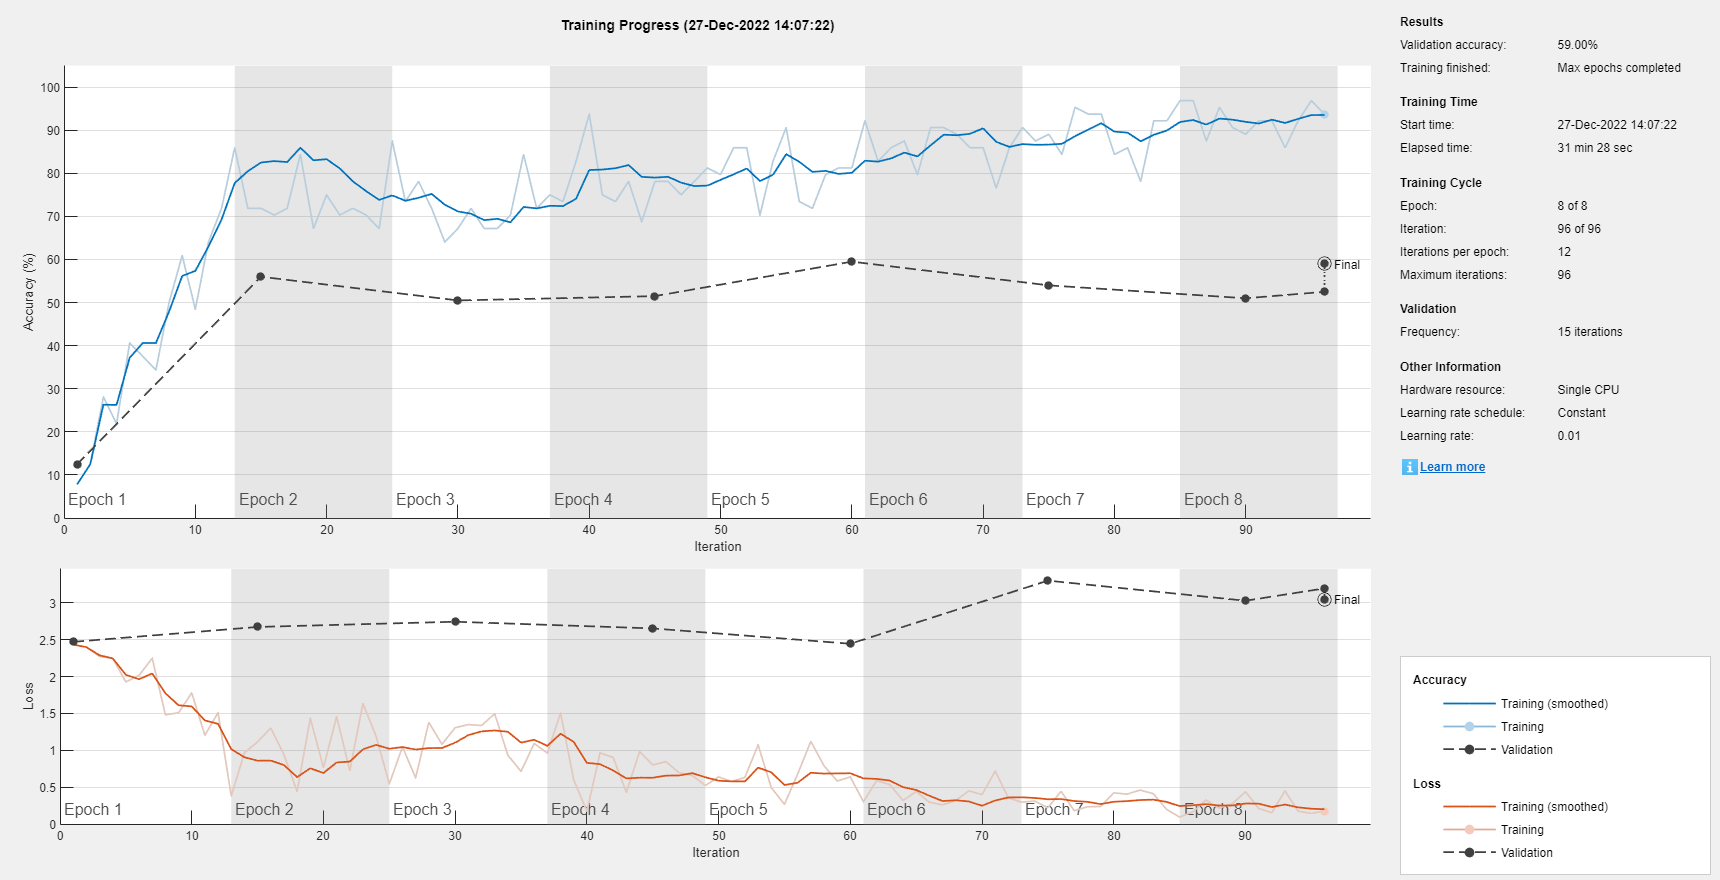

lgraph = layerGraph(net);
[learnableLayer,classLayer] = findLayersToReplace(lgraph);
numClasses = numel(categories(trainImds.Labels));

augimds = augmentedImageDatastore(inputSize(1:2),trainImds, 'ColorPreprocessing',"gray2rgb");
miniBatchSize = 64;
valFrequency = 15;

opts = trainingOptions('sgdm',...
    'InitialLearnRate',  0.01, ...
    'ValidationData', testImds, ...
    'MaxEpochs', 8, ...
    'MiniBatchSize',miniBatchSize,...
    'ValidationFrequency',valFrequency, ...
    'Shuffle','every-epoch',...
    'Plots', 'training-progress',...
    'Verbose',false);


if isa(learnableLayer,"nnet.cnn.layer.FullyConnectedLayer")
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        Name="new_fc", ...
        WeightLearnRateFactor=10, ...
        BiasLearnRateFactor=10);
elseif isa(learnableLayer,"nnet.cnn.layer.Convolution2DLayer")
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        Name="new_conv", ...
        WeightLearnRateFactor=10, ...
        BiasLearnRateFactor=10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

newClassLayer = classificationLayer(Name="new_classoutput");
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

trainImds.ReadFcn = @(x)imresize(imread(x),'OutputSize',[299 299]);
testImds.ReadFcn = @(x)imresize(imread(x),'OutputSize',[299 299]);
augmenter = imageDataAugmenter('RandRotation',[0 180],'RandXTranslation', [-5 5], ...
    'RandYTranslation',[-5 5]);
augimds = augmentedImageDatastore([299 299 3],trainImds,...
    'DataAugmentation',augmenter, 'ColorPreprocessing','gray2rgb');
trainedNet = trainNetwork(augimds,lgraph,opts);


ypred = trainedNet.classify(testImds);
cnnAccuracy = sum(ypred == testImds.Labels)/numel(testImds.Labels)*100

cnnAccuracy = 59

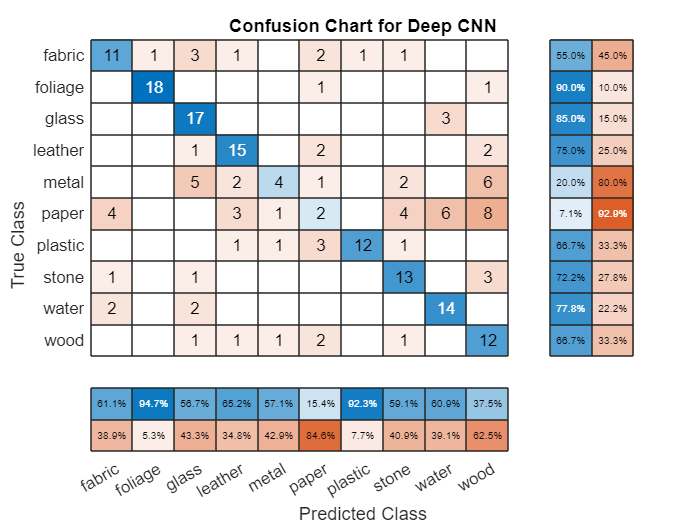

figure
cchart = confusionchart(testImds.Labels,ypred);
cchart.Title = 'Confusion Chart for Deep CNN';
cchart.RowSummary = 'row-normalized';
cchart.ColumnSummary = 'column-normalized';

## Functions

function [learnableLayer,classLayer] = findLayersToReplace(lgraph)

if ~isa(lgraph,"nnet.cnn.LayerGraph")
    error("Argument must be a LayerGraph object.")
end

src = string(lgraph.Connections.Source);
dst = string(lgraph.Connections.Destination);
layerNames = string({lgraph.Layers.Name}');

isClassificationLayer = arrayfun(@(l) ...
    (isa(l,"nnet.cnn.layer.ClassificationOutputLayer")|isa(l,"nnet.layer.ClassificationLayer")), ...
    lgraph.Layers);

if sum(isClassificationLayer) ~= 1
    error("Layer graph must have a single classification layer.")
end
classLayer = lgraph.Layers(isClassificationLayer);

currentLayerIdx = find(isClassificationLayer);
while true
    
    if numel(currentLayerIdx) ~= 1
        error("Layer graph must have a single learnable layer preceding the classification layer.")
    end
    
    currentLayerType = class(lgraph.Layers(currentLayerIdx));
    isLearnableLayer = ismember(currentLayerType, ...
        ["nnet.cnn.layer.FullyConnectedLayer","nnet.cnn.layer.Convolution2DLayer"]);
    
    if isLearnableLayer
        learnableLayer =  lgraph.Layers(currentLayerIdx);
        return
    end
    
    currentDstIdx = find(layerNames(currentLayerIdx) == dst);
    currentLayerIdx = find(src(currentDstIdx) == layerNames);
end
end
